# Figure of PCC correlation  KS vs ID

Get the data for a scatter plot with results of regularized permutation DFA for males and females separately

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll7);
% obtain the matrices of the percent of classification above chance level
Mat_PCCKS_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCKS_std = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCID_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCID_std = nan(length(UGroup)+1,2);% First column =males; second column = females
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCKS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1) - PCCperm_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCKS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2) + PCCperm_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCKS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCperm_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCKS_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2)+PCCperm_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCKS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1)-PCCperm_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCKS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCperm_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCKS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2)+PCCperm_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCKS_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2)+PCCperm_females_mean_std(NPC_opt_M_ind,2);


for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAID_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCrand_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAID_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCrand_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCID_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1) - PCCrand_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCID_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2) + PCCrand_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCID_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCrand_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCID_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2)+PCCrand_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAID_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCrand_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAID_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCrand_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCID_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1)-PCCrand_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCID_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCrand_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCID_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2)+PCCrand_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCID_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2)+PCCrand_females_mean_std(NPC_opt_M_ind,2);

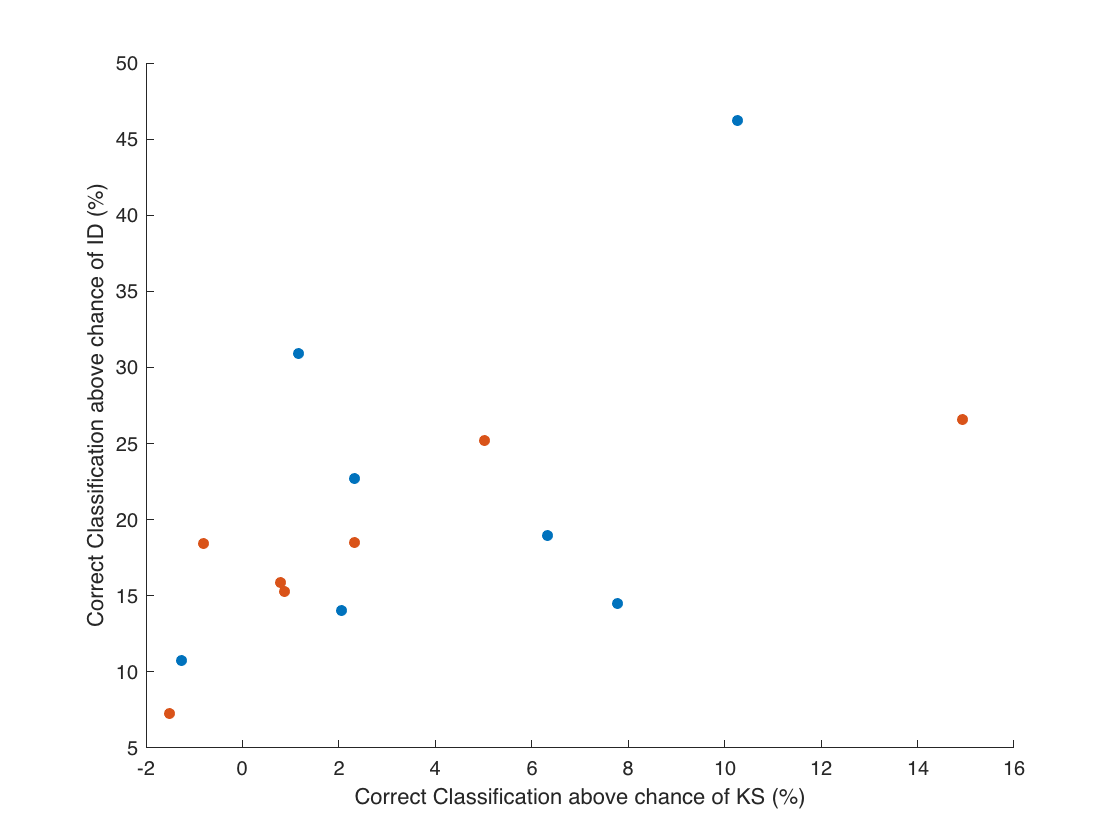

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
figure()
scatter(Mat_PCCKS_mean(1:length(UGroup),1), Mat_PCCID_mean(1:length(UGroup),1),30,ColorCode(1,:),"filled",'o')
hold on
scatter(Mat_PCCKS_mean(1:length(UGroup),2), Mat_PCCID_mean(1:length(UGroup),2),30,ColorCode(2,:),"filled",'o')
% hold on
% errorbar(Mat_PCCKS_mean(:,1), Mat_PCCID_mean(:,1),Mat_PCCID_std(:,1), Mat_PCCID_std(:,1),Mat_PCCKS_std(:,1), Mat_PCCKS_std(:,1), 'k.','LineWidth',1.5)
% hold on
% errorbar(Mat_PCCKS_mean(:,2), Mat_PCCID_mean(:,2),Mat_PCCID_std(:,2), Mat_PCCID_std(:,2),Mat_PCCKS_std(:,2), Mat_PCCKS_std(:,2), 'k.','LineWidth',1.5)
%ylim([50 100])
box off
ylabel('Correct Classification above chance of ID (%)')
xlabel('Correct Classification above chance of KS (%)')
% XTL = get(gca,'XTickLabel');
% XTL{end} = 'All';
% set(gca, 'XTickLabel', XTL);  
% set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
% hold on
% text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off

Consider classification of saline Bats ID only

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll7);
% obtain the matrices of the percent of classification above chance level
Mat_PCCKS_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCKS_std = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCID_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCID_std = nan(length(UGroup)+1,2);% First column =males; second column = females
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFA_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCKS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1) - PCCperm_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCKS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2) + PCCperm_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCKS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCperm_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCKS_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2)+PCCperm_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCperm_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFA_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCperm_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCKS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1)-PCCperm_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCKS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCperm_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCKS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2)+PCCperm_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCKS_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2)+PCCperm_females_mean_std(NPC_opt_M_ind,2);


for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCrand_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCrand_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCID_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1) - PCCrand_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCID_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2) + PCCrand_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCID_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCrand_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCID_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2)+PCCrand_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'PCCrand_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'PCCrand_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCID_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1)-PCCrand_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCID_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1)-PCCrand_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCID_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2)+PCCrand_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCID_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2)+PCCrand_females_mean_std(NPC_opt_M_ind,2);

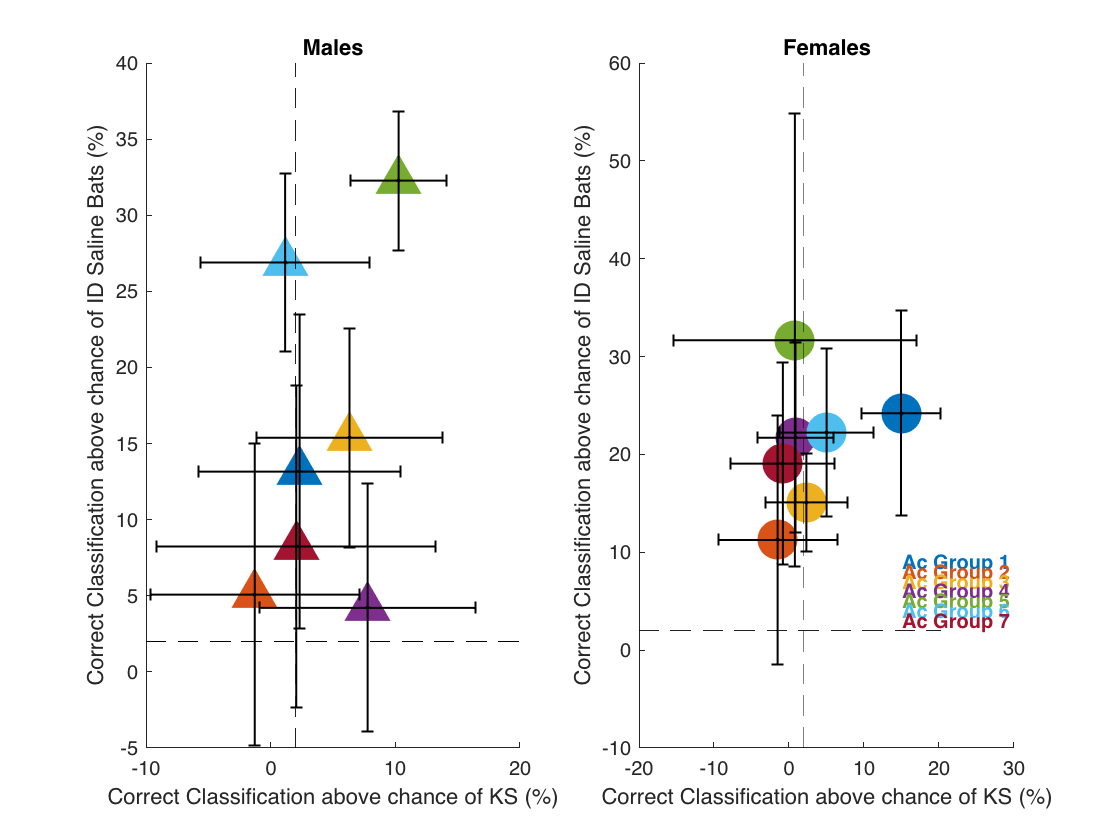

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
figure()
subplot(1,2,1)
scatter(Mat_PCCKS_mean(1:length(UGroup),1), Mat_PCCID_mean(1:length(UGroup),1),400,ColorCode(1:length(UGroup),:),"filled",'^')
hold on
errorbar(Mat_PCCKS_mean(1:length(UGroup),1), Mat_PCCID_mean(1:length(UGroup),1),Mat_PCCID_std(1:length(UGroup),1), Mat_PCCID_std(1:length(UGroup),1),Mat_PCCKS_std(1:length(UGroup),1), Mat_PCCKS_std(1:length(UGroup),1), 'k.','LineWidth',1)

box off
ylabel('Correct Classification above chance of ID Saline Bats (%)')
xlabel('Correct Classification above chance of KS (%)')
vline(2, 'k--')
hline(2,'k--')
title('Males')
subplot(1,2,2)
scatter(Mat_PCCKS_mean(1:length(UGroup),2), Mat_PCCID_mean(1:length(UGroup),2),400,ColorCode(1:length(UGroup),:),"filled",'o')
hold on
errorbar(Mat_PCCKS_mean(1:length(UGroup),2), Mat_PCCID_mean(1:length(UGroup),2),Mat_PCCID_std(1:length(UGroup),2), Mat_PCCID_std(1:length(UGroup),2),Mat_PCCKS_std(1:length(UGroup),2), Mat_PCCKS_std(1:length(UGroup),2), 'k.','LineWidth',1)
%ylim([50 100])
box off
ylabel('Correct Classification above chance of ID Saline Bats (%)')
xlabel('Correct Classification above chance of KS (%)')
title('Females')
hline(2,'k--')
vline(2, 'k--')

% XTL = get(gca,'XTickLabel');
% XTL{end} = 'All';
% set(gca, 'XTickLabel', XTL);  
% set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
% legend('Male', 'Female')
for gg=1:length(UGroup)
    text(15,10-1*gg,sprintf('Ac Group %d', gg),'color',ColorCode(gg,:), 'FontWeight','bold')
end
% text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
% hold on
% text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')    
% hold on
% text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off

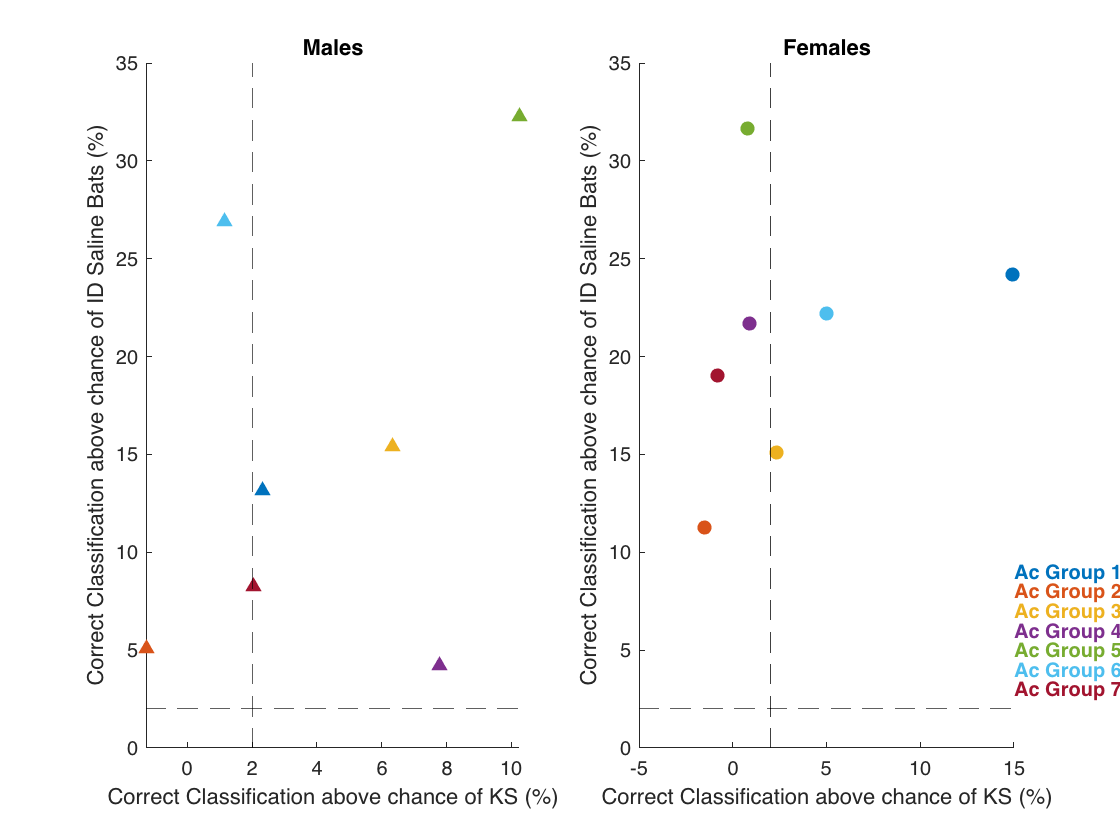


figure()
subplot(1,2,1)
scatter(Mat_PCCKS_mean(1:length(UGroup),1), Mat_PCCID_mean(1:length(UGroup),1),50,ColorCode(1:length(UGroup),:),"filled",'^')
% hold on
% errorbar(Mat_PCCKS_mean(:,1), Mat_PCCID_mean(:,1),Mat_PCCID_std(:,1), Mat_PCCID_std(:,1),Mat_PCCKS_std(:,1), Mat_PCCKS_std(:,1), 'k.','LineWidth',1)

box off
ylabel('Correct Classification above chance of ID Saline Bats (%)')
xlabel('Correct Classification above chance of KS (%)')
vline(2, 'k--')
hline(2,'k--')
title('Males')
subplot(1,2,2)
scatter(Mat_PCCKS_mean(1:length(UGroup),2), Mat_PCCID_mean(1:length(UGroup),2),50,ColorCode(1:length(UGroup),:),"filled",'o')
% hold on
% errorbar(Mat_PCCKS_mean(:,2), Mat_PCCID_mean(:,2),Mat_PCCID_std(:,2), Mat_PCCID_std(:,2),Mat_PCCKS_std(:,2), Mat_PCCKS_std(:,2), 'k.','LineWidth',1)
%ylim([50 100])
box off
ylabel('Correct Classification above chance of ID Saline Bats (%)')
xlabel('Correct Classification above chance of KS (%)')
title('Females')
hline(2,'k--')
vline(2, 'k--')

for gg=1:length(UGroup)
    text(15,10-1*gg,sprintf('Ac Group %d', gg),'color',ColorCode(gg,:), 'FontWeight','bold')
end
hold off

Get the barplot figure of the percent ofclassification correct of ID of Saline bats per sex and Acoustic groups

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
UGroup = unique(TmicAll7);
Mat_PCC_mean = nan(2*(length(UGroup)+1),2);
Mat_PCC_std = nan(2*(length(UGroup)+1),2);
P_males = nan(length(UGroup)+1,1); % for each acoustic group (rows) p-value of the permutation test comparing the Loss of the true classifier with that of the random bootstrap classifier 
P_females = nan(length(UGroup)+1,1);% for each acoustic group (rows) p-value of the permutation test comparing the Loss of the true classifier with that of the random bootstrap classifier
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std', 'L_males', 'PCCrand_males_mean_std', 'Lrand_males','MeanPCCrand_males_bootstrap');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std', 'L_females', 'PCCrand_females_mean_std', 'Lrand_females','MeanPCCrand_females_bootstrap');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2-1,2) = PCCrand_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_mean(GR*2,2) = PCCrand_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2-1,2) = PCCrand_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
    Mat_PCC_std(GR*2,2) = PCCrand_females_mean_std(NPC_opt_F_ind,2);
    P_males(GR)=sum(MeanPCCrand_males_bootstrap>=mean(100-100*L_males{PC_val_M==NPC_opt_M}))/length(MeanPCCrand_males_bootstrap);
    P_females(GR)=sum(MeanPCCrand_females_bootstrap>=mean(100-100*L_females{PC_val_F==NPC_opt_F}))/length(MeanPCCrand_females_bootstrap);
    
   
%     % Run a fisher exact test for each condition
%     Tbl_male = table(round([PCC_males_mean_std(NPC_opt_M_ind,1); PCCrand_males_mean_std(NPC_opt_M_ind,1)]), round([100-PCC_males_mean_std(NPC_opt_M_ind,1); 100-PCCrand_males_mean_std(NPC_opt_M_ind,1)]), 'RowNames',{'ID','Random'},'VariableNames',{'Correct Classification','Error'});
%     Tbl_female = table(round([PCC_females_mean_std(NPC_opt_M_ind,1); PCCrand_females_mean_std(NPC_opt_M_ind,1)]), round([100-PCC_females_mean_std(NPC_opt_M_ind,1); 100-PCCrand_females_mean_std(NPC_opt_M_ind,1)]), 'RowNames',{'ID','Random'},'VariableNames',{'Correct Classification','Error'});
%     [Hmale,p_male,stats] = fishertest(Tbl_male,'Tail','right','Alpha',0.01);
%     if p_male<0.05
%         fprintf(1,'Male Acoustic Grp %d: There is %.2f chance of better classifying the ID of bats with the exact (non-random) classifier with p-value = %.4f\n',GR,stats.OddsRatio,p_male)
%     end
%     [Hfemale,p_female,stats] = fishertest(Tbl_female,'Tail','right','Alpha',0.01);
%     if p_female<0.05
%         fprintf(1,'Female Acoustic Grp %d: There is %.2f chance of better classifying the ID of bats with the exact (non-random) classifier with p-value = %.4f\n',GR,stats.OddsRatio,p_female)
%     end
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','L_males','PCC_males_mean_std', 'PCCrand_males_mean_std','MeanPCCrand_males_bootstrap')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','L_females','PCC_females_mean_std', 'PCCrand_females_mean_std','MeanPCCrand_females_bootstrap')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCC_mean(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2-1,2) = PCCrand_males_mean_std(NPC_opt_M_ind,1);
Mat_PCC_mean(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_mean(GR*2,2) = PCCrand_females_mean_std(NPC_opt_F_ind,1);
Mat_PCC_std(GR*2-1,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2-1,2) = PCCrand_males_mean_std(NPC_opt_M_ind,2);
Mat_PCC_std(GR*2,1) = PCC_females_mean_std(NPC_opt_F_ind,2);
Mat_PCC_std(GR*2,2) = PCCrand_females_mean_std(NPC_opt_F_ind,2);
P_males(GR)=sum(MeanPCCrand_males_bootstrap>=mean(100-100*L_males{PC_val_M==NPC_opt_M}))/length(MeanPCCrand_males_bootstrap);
P_females(GR)=sum(MeanPCCrand_females_bootstrap>=mean(100-100*L_females{PC_val_F==NPC_opt_F}))/length(MeanPCCrand_females_bootstrap);
    

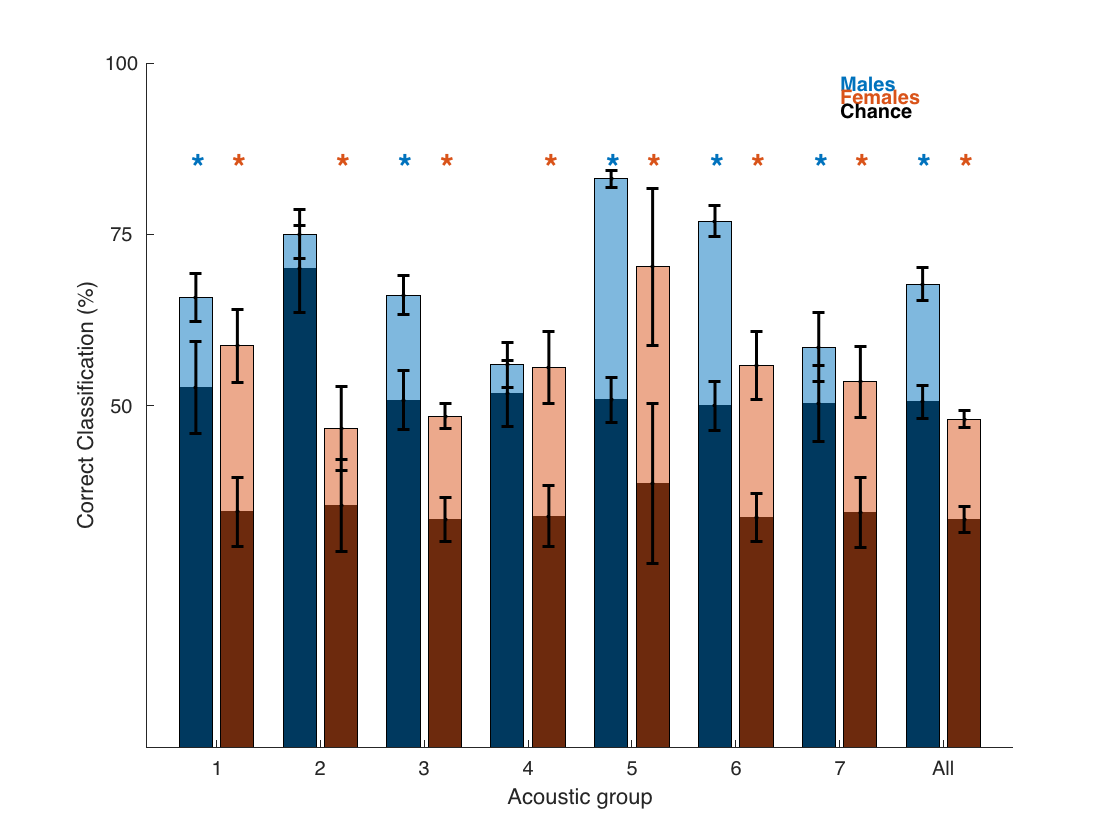


figure()
GR = length(UGroup);
X = reshape([1:GR+1; 1:GR+1] + repmat([-0.2;0.2], 1, GR+1), 1,(GR+1)*2);
bar(X,Mat_PCC_mean(:,2),'FaceColor', 'k')
hold on
B=bar(X,Mat_PCC_mean(:,1),'FaceColor', 'flat', 'FaceAlpha', 0.5);
B.CData = repmat([ColorCode(1,:); ColorCode(2,:)],8,1);
hold on
errorbar(X,Mat_PCC_mean(:,2),Mat_PCC_std(:,2), Mat_PCC_std(:,2), 'k.','LineWidth',1.5)
hold on
errorbar(X,Mat_PCC_mean(:,1),Mat_PCC_std(:,1), Mat_PCC_std(:,1), 'k.','LineWidth',1.5)
ylim([0 100])
box off
ylabel('Correct Classification (%)')
xlabel('Acoustic group')
XTL = get(gca,'XTickLabel');
XTL{end} = 'All';
set(gca, 'XTickLabel', XTL);  
set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
hold on
text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')
hold on
text(7,93,'Chance','color','k', 'FontWeight', 'bold')
for GR=1:length(UGroup)+1
    if P_males(GR)<0.01
        text(GR-0.25, 85, '*','FontSize',18,'Color',ColorCode(1,:),'FontWeight','bold')
    end
    if P_females(GR)<0.01
        text(GR+0.15, 85, '*','FontSize',18,'Color',ColorCode(2,:),'FontWeight','bold')
    end
end

hold off

Compare theID  PCC of Saline vs Kanamycin

LocalDataDir = '/Users/elie/Documents/DeafBats/Data';
load(fullfile(LocalDataDir, 'Data4_DeafBats_CatCalls.mat'),'TmicAll7');
UGroup = unique(TmicAll7);
% obtain the matrices of the percent of classification above chance level
Mat_PCCIDK_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCIDK_std = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCIDS_mean = nan(length(UGroup)+1,2);% First column =males; second column = females
Mat_PCCIDS_std = nan(length(UGroup)+1,2);% First column =males; second column = females
for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDK_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDK_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCIDK_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCIDK_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCIDK_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCIDK_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDK_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDK_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCIDK_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCIDK_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCIDK_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCIDK_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2);


for gg=1:length(UGroup)
    GR = UGroup(gg);
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_MaleAcGroup%d.mat', GR)),  'PC_val_M', 'NPC_opt_M','PCC_males_mean_std');
    load(fullfile(LocalDataDir, sprintf('DeafBats_RegularizedPermDFAIDS_FemaleAcGroup%d.mat', GR)),  'PC_val_F', 'NPC_opt_F','PCC_females_mean_std');
    NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
    NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
    Mat_PCCIDS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
    Mat_PCCIDS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
    Mat_PCCIDS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1);
    Mat_PCCIDS_std(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,2);
end

load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_MaleCalls.mat'), 'PC_val_M', 'NPC_opt_M','PCC_males_mean_std')
load(fullfile(LocalDataDir, 'DeafBats_RegularizedPermDFAIDS_FemaleCalls.mat'), 'PC_val_F', 'NPC_opt_F','PCC_females_mean_std')
GR=8;
NPC_opt_M_ind = find(PC_val_M==NPC_opt_M);
NPC_opt_F_ind = find(PC_val_F==NPC_opt_F);
Mat_PCCIDS_mean(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,1);
Mat_PCCIDS_mean(GR,2) = PCC_females_mean_std(NPC_opt_F_ind,1);
Mat_PCCIDS_std(GR,1) = PCC_males_mean_std(NPC_opt_M_ind,2);
Mat_PCCIDS_std(GR,2) = PCC_females_mean_std(NPC_opt_M_ind,2);

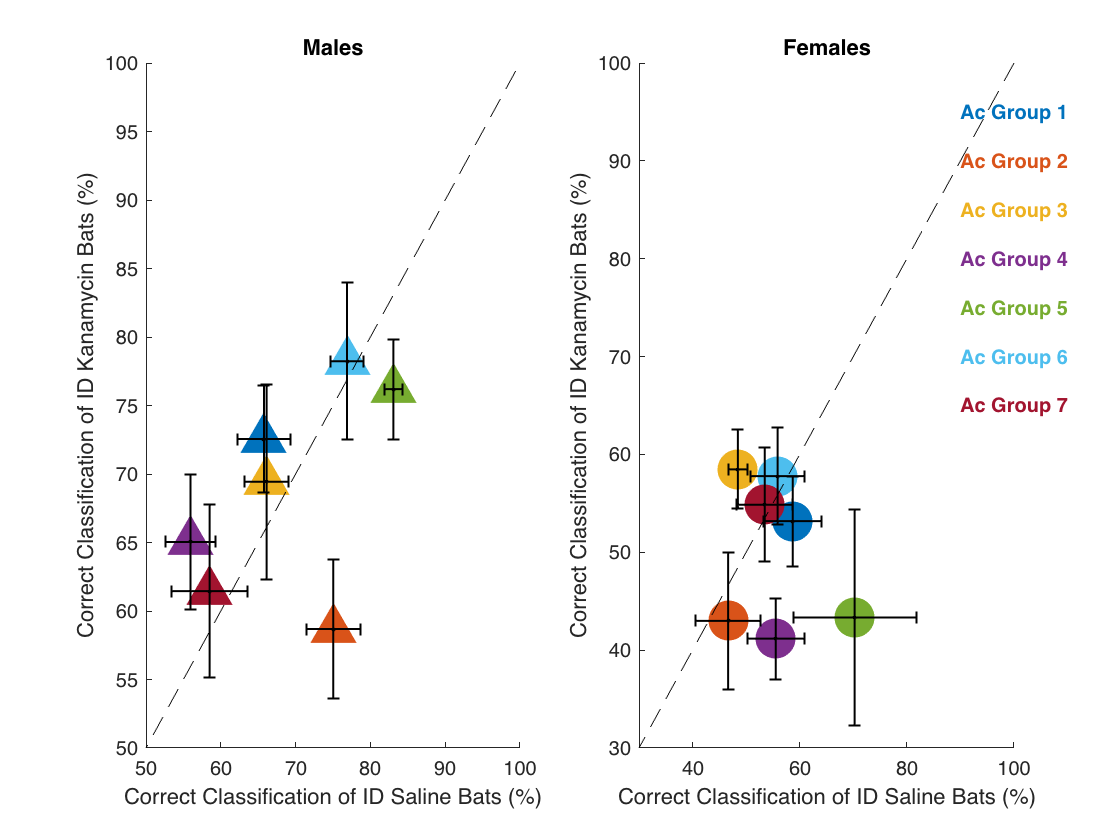

ColorCode = [get(groot, 'DefaultAxesColorOrder'); 0 1 1; 0.5 0.5 0.5; 1 0 0 ; 0 1 0 ; 0 0 1; 1 0 1; 0 0 0];
figure()
subplot(1,2,1)
scatter(Mat_PCCIDS_mean(1:length(UGroup),1), Mat_PCCIDK_mean(1:length(UGroup),1),400,ColorCode(1:length(UGroup),:),"filled",'^')
hold on
errorbar(Mat_PCCIDS_mean(1:length(UGroup),1), Mat_PCCIDK_mean(1:length(UGroup),1),Mat_PCCIDK_std(1:length(UGroup),1), Mat_PCCIDK_std(1:length(UGroup),1),Mat_PCCIDS_std(1:length(UGroup),1), Mat_PCCIDS_std(1:length(UGroup),1), 'k.','LineWidth',1)

box off
ylabel('Correct Classification of ID Kanamycin Bats (%)')
xlabel('Correct Classification of ID Saline Bats (%)')
ylim([50 100])
xlim([50 100])
plot([0 100],[0 100], 'k--')
title('Males')
subplot(1,2,2)
scatter(Mat_PCCIDS_mean(1:length(UGroup),2), Mat_PCCIDK_mean(1:length(UGroup),2),400,ColorCode(1:length(UGroup),:),"filled",'o')
hold on
errorbar(Mat_PCCIDS_mean(1:length(UGroup),2), Mat_PCCIDK_mean(1:length(UGroup),2),Mat_PCCIDK_std(1:length(UGroup),2), Mat_PCCIDK_std(1:length(UGroup),2),Mat_PCCIDS_std(1:length(UGroup),2), Mat_PCCIDS_std(1:length(UGroup),2), 'k.','LineWidth',1)
ylim([30 100])
xlim([30 100])
box off
ylabel('Correct Classification of ID Kanamycin Bats (%)')
xlabel('Correct Classification of ID Saline Bats (%)')
title('Females')
plot([0 100],[0 100], 'k--')

% XTL = get(gca,'XTickLabel');
% XTL{end} = 'All';
% set(gca, 'XTickLabel', XTL);  
% set(gca, 'YTick', [50 75 100], 'YTickLabel', [50 75 100]);
% legend('Male', 'Female')
for gg=1:length(UGroup)
    text(90,100-5*gg,sprintf('Ac Group %d', gg),'color',ColorCode(gg,:), 'FontWeight','bold')
end
% text(7,97,'Males','color',ColorCode(1,:), 'FontWeight','bold')
% hold on
% text(7,95,'Females','color',ColorCode(2,:), 'FontWeight', 'bold')    
% hold on
% text(7,93,'Chance','color','k', 'FontWeight', 'bold')
hold off

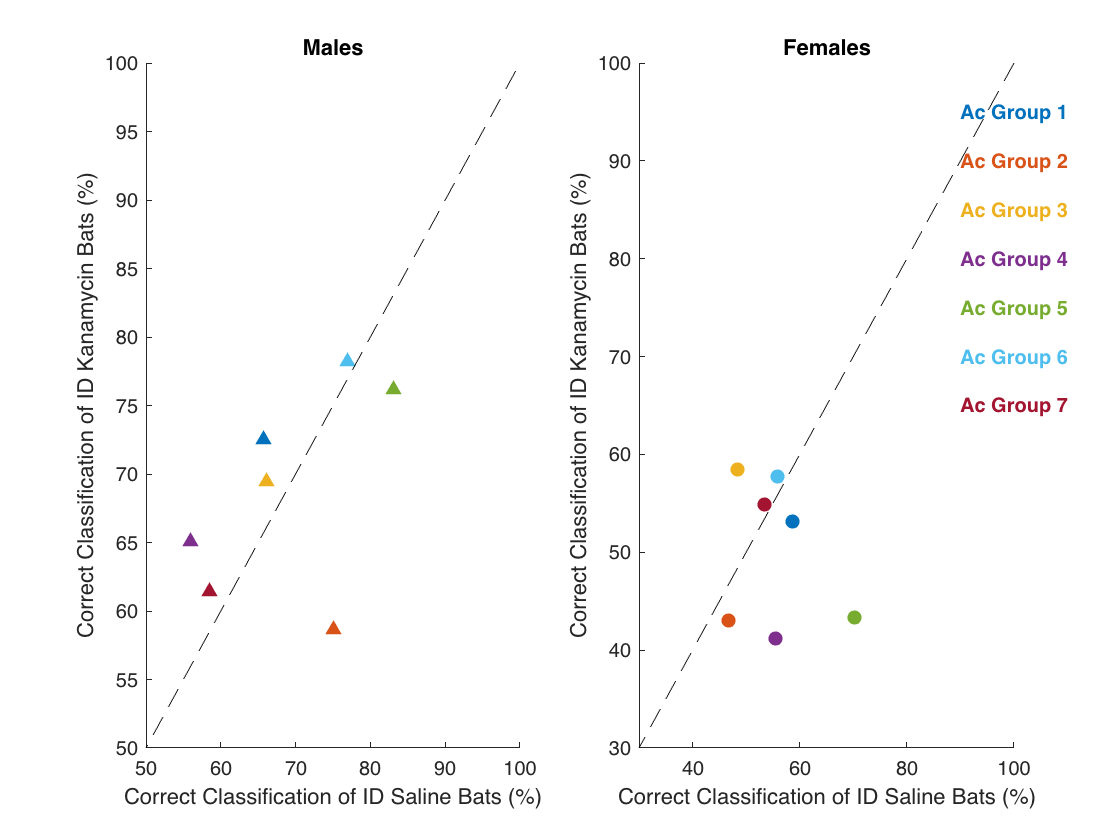


figure()
subplot(1,2,1)
scatter(Mat_PCCIDS_mean(1:length(UGroup),1), Mat_PCCIDK_mean(1:length(UGroup),1),50,ColorCode(1:length(UGroup),:),"filled",'^')
% hold on
% errorbar(Mat_PCCKS_mean(:,1), Mat_PCCID_mean(:,1),Mat_PCCID_std(:,1), Mat_PCCID_std(:,1),Mat_PCCKS_std(:,1), Mat_PCCKS_std(:,1), 'k.','LineWidth',1)

box off
ylabel('Correct Classification of ID Kanamycin Bats (%)')
xlabel('Correct Classification of ID Saline Bats (%)')
hold on
plot([0 100],[0 100], 'k--')
ylim([50 100])
xlim([50 100])

title('Males')
hold off
subplot(1,2,2)
scatter(Mat_PCCIDS_mean(1:length(UGroup),2), Mat_PCCIDK_mean(1:length(UGroup),2),50,ColorCode(1:length(UGroup),:),"filled",'o')
% hold on
% errorbar(Mat_PCCKS_mean(:,2), Mat_PCCID_mean(:,2),Mat_PCCID_std(:,2), Mat_PCCID_std(:,2),Mat_PCCKS_std(:,2), Mat_PCCKS_std(:,2), 'k.','LineWidth',1)

box off
ylabel('Correct Classification of ID Kanamycin Bats (%)')
xlabel('Correct Classification of ID Saline Bats (%)')
title('Females')
hold on
plot([0 100],[0 100], 'k--')
ylim([30 100])
xlim([30 100])
for gg=1:length(UGroup)
    text(90,100-5*gg,sprintf('Ac Group %d', gg),'color',ColorCode(gg,:), 'FontWeight','bold')
end
hold off